clear all,clear clc, format long;
% Instancie su código PUCP 
rng(20211755);
% Instancie los parámetros de la simulación
N=10^5;
lambda=800; % Completar
velocidad_transmision=5*10^6; % Completar
pkt_size=5000; % Completar
lamda_array = [800]

lamda_array =    800


⁕⁕⁕ Valor de arrival rate = 800
⁕ Tiempo promedio en el sistema (T) en el modo M/D/1: 0.0030034
⁕ Tiempo promedio en el sistema (T) en el modo M/M/1: 0.0050682
⁕ Tiempo promedio en la cola (W) en el modo M/D/1: 0.0020034
⁕ Tiempo promedio en la cola (W) en el modo M/M/1: 0.0040676


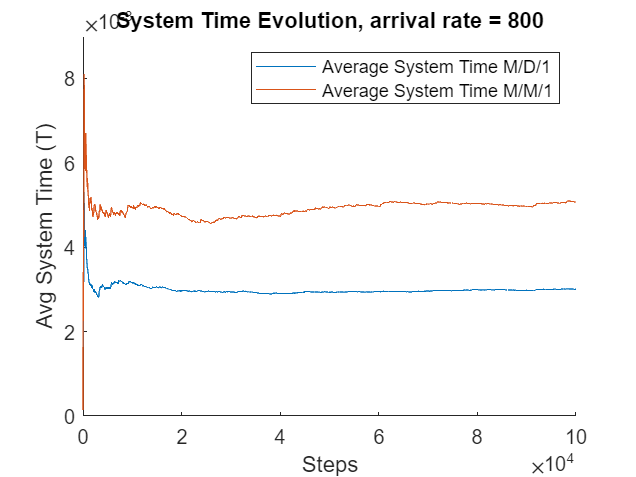

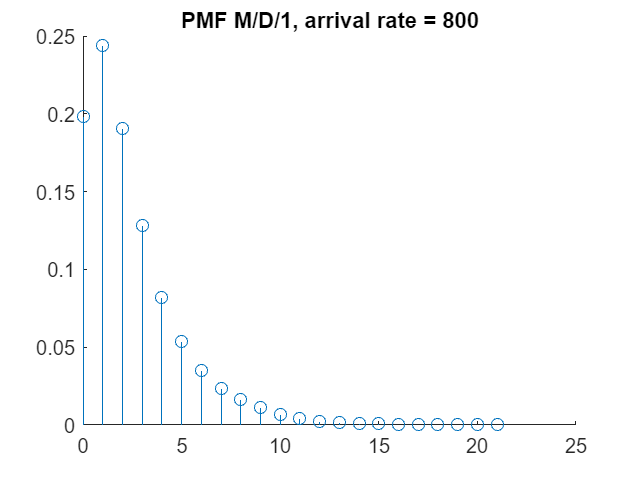

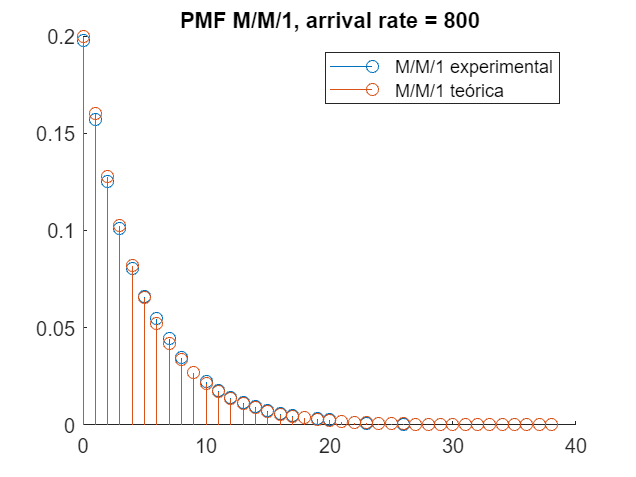

⁕ El número promedio de paquetes en el sistema para el caso de M/D/1: 4.0652
⁕ El número promedio de paquetes en el sistema para el caso de M/M/1: 2.4089
⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕


mm1_array = 1.0e+02 *

   8.000000000000000   0.000040675796752   0.000050681864012


md1_array = 1.0e+02 *

   8.000000000000000   0.000020034283321   0.000030034283321


% Ingrese los parámetros a la función
[mm1_array,md1_array] = comparacion_mm1_md1(N,lamda_array,velocidad_transmision,pkt_size)

mm1_array(1,1)

ans =    800


mm1_array(1,2)

ans =    0.004067579675188


mm1_array(1,3)

ans =    0.005068186401193



md1_array(1,1)

ans =    800


md1_array(1,2)

ans =    0.002003428332125


md1_array(1,3)

ans =    0.003003428332127


function [mm1_array,md1_array]=comparacion_mm1_md1(n_samples,arrival_rate_array,transmision_rate,packet_size)
% Salidas de la función:
% Para cada tipo de cola, se obtiene un arreglo de tamaño nx3
% donde "n" es la cantidad de valores en el arreglo de los arrival rates.
n = length(arrival_rate_array);
mm1_array = zeros(n,3);
md1_array = zeros(n,3);
% Estructura de cada fila:
% fila = [valor de arrival rate, tiempo promedio en la cola, tiempo promedio en el sistema]

% Consideramos una estructura iterativa para completar las salidas por cada valor del arreglo de arrival rates:
for k=1:n
    arrival_rate = arrival_rate_array(k);
    % Generamos las llegadas en base al número de muestras
    arrival_times = genera_poisson(arrival_rate,n_samples);
    % para el caso de M/D/1 calculamos la duración de cada paquete
    pkt_sizes_md1= 5000*ones(1,n_samples);
    pkt_duration_md1=pkt_sizes_md1/transmision_rate;
    % para el caso de M/M/1 realizamos el proceso similar
    mean_packet_size = 1/packet_size;
    pkt_sizes_mm1= genera_exponencial(mean_packet_size,n_samples);
    pkt_duration_mm1= pkt_sizes_mm1/transmision_rate;
    % Obtenemos los tiempos de partida para ambos casos
    depature_times_md1=get_departure_times(arrival_times,pkt_duration_md1);
    depature_times_mm1=get_departure_times(arrival_times,pkt_duration_mm1);
    % Con los tiempos de salida podemos determinar el tiempo que toman en el
    % sistema realizando una resta con los tiempos de llegada
    % Para el caso de M/D/1
    sistem_time_md1=depature_times_md1-arrival_times;
    tiempo_promedio_sistema_md1=mean(sistem_time_md1);
    % Para el caso de M/M/1
    sistem_time_mm1=depature_times_mm1-arrival_times;
    tiempo_promedio_sistema_mm1=mean(sistem_time_mm1);
    % Imprimimos el valor de lambda actual
    disp("⁕⁕⁕ Valor de arrival rate = "+num2str(arrival_rate))
    % Realizamos la impresión de los tiempos promedios en el sistema (T)
    disp("⁕ Tiempo promedio en el sistema (T) en el modo M/D/1: "+num2str(tiempo_promedio_sistema_md1))
    disp("⁕ Tiempo promedio en el sistema (T) en el modo M/M/1: "+num2str(tiempo_promedio_sistema_mm1))
    % Con los tiempos promedios en el sistema, duración del paquete y arrival
    % rate podemos hallar el tiempo promedio en la cola
    queue_time_md1=depature_times_md1-pkt_duration_md1-arrival_times;
    mean_queue_time_md1=mean(queue_time_md1);
    queue_time_mm1=depature_times_mm1-pkt_duration_mm1-arrival_times;
    mean_queue_time_mm1=mean(queue_time_mm1);
    disp("⁕ Tiempo promedio en la cola (W) en el modo M/D/1: "+num2str(mean_queue_time_md1))
    disp("⁕ Tiempo promedio en la cola (W) en el modo M/M/1: "+num2str(mean_queue_time_mm1))
    
    % Almacenamos los valores calculados en los arreglos de salida:
    mm1_array(k,1) = arrival_rate;
    mm1_array(k,2) = mean_queue_time_mm1;
    mm1_array(k,3) = tiempo_promedio_sistema_mm1;

    md1_array(k,1) = arrival_rate;
    md1_array(k,2) = mean_queue_time_md1;
    md1_array(k,3) = tiempo_promedio_sistema_md1;
    % Para el análisis de la cantidad de paquetes a eliminar para la
    % determinación del tiempo de convergencia podemos utilizar un promedio
    % acumulativo que permita determinar hasta que cantidad de paquetes el
    % sistema converge (hacer uso de los cursores)
    pasos= 1:n_samples;
    promedio_md1 = zeros(1,n_samples);
    promedio_mm1 = zeros(1,n_samples);
    for i=1:n_samples
        promedio_md1(i)=mean(sistem_time_md1(1:i));
        promedio_mm1(i)=mean(sistem_time_mm1(1:i));
    end
    figure;
    hold on;
    plot(pasos,promedio_md1,pasos,promedio_mm1);
    legend("Average System Time M/D/1","Average System Time M/M/1");
    title("System Time Evolution, arrival rate = "+num2str(arrival_rate));
    xlabel("Steps");
    ylabel("Avg System Time (T)");
    hold off;
    % Ahora para graficar la PMF trealizamos lo siguiente
    % para el caso de la M/D/1 
    [event_times_md1,ocupancia_md1]=calcula_ocupancia(arrival_times,depature_times_md1);
    pmf_estable_md1=calcula_pmf_estado_estable(event_times_md1,ocupancia_md1);
    [estados_md1,upon_arrival]=calcula_pmf_upon_arrival(ocupancia_md1);
    figure;
    hold on;
    stem(estados_md1,pmf_estable_md1);
    title("PMF M/D/1, arrival rate = "+num2str(arrival_rate));
    hold off;
    % para el caso de la M/M/1 realizaremos un proceso análogo al caso anterior
    % pero realizaremos el contraste con la fórmula teórica
    [event_times_mm1,ocupancia_mm1]=calcula_ocupancia(arrival_times,depature_times_mm1);
    pmf_estable_mm1=calcula_pmf_estado_estable(event_times_mm1,ocupancia_mm1);
    [estados_mm1,upon_arrival]=calcula_pmf_upon_arrival(ocupancia_mm1);
    % hallamos rho
    miu = transmision_rate/packet_size;
    ro = arrival_rate/miu;
    pmf_teorica=(1-ro)*(ro.^estados_mm1);
    figure;
    hold on;
    stem(estados_mm1,pmf_estable_mm1);
    stem(estados_mm1,pmf_teorica);
    hold off;
    title("PMF M/M/1, arrival rate = "+num2str(arrival_rate));
    legend("M/M/1 experimental","M/M/1 teórica");
    % Finalmente realizamos la verificación del valor esperado empíricamente 
    esperado_mm1=0;
    for i=1:length(pmf_estable_mm1)
        esperado_mm1=esperado_mm1+pmf_estable_mm1(i)*estados_mm1(i);
    end
    esperado_md1=0;
    for i=1:length(pmf_estable_md1)
        esperado_md1=esperado_md1+pmf_estable_md1(i)*estados_md1(i);
    end
    disp("⁕ El número promedio de paquetes en el sistema para el caso de M/D/1: "+num2str(esperado_mm1))
    disp("⁕ El número promedio de paquetes en el sistema para el caso de M/M/1: "+num2str(esperado_md1))
    disp("⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕⁕")
    end
end


% Funciones base
function departure_times = get_departure_times(arrival_times,tx_delay)
N = length (arrival_times);
departure_times = zeros(1,N);
departure_times(1) = arrival_times(1) + tx_delay(1);%Se modifico tx_delay
for i = 2:N
if departure_times(i-1) <= arrival_times(i)
departure_times(i) = arrival_times(i) + tx_delay(i);%se modifico el tx_delay
else
departure_times(i) = departure_times(i-1) + tx_delay(i);%se modifico el tx_delay
end
end
end
%para los incisos c y d 
function out = genera_poisson(lambda,N)
inter_arrivals = genera_exponencial(lambda,N); 
cumulative = conv(inter_arrivals,ones(1,N));
out = cumulative(1:N);
end
function out = genera_exponencial(lambda,N)
Y = rand(1,N);
out = (-log(1-Y))/lambda; 
end
%para el inciso l
function [event_times, ocupancia] = calcula_ocupancia(arrival_times, departure_times)
% Se genera un arreglo "eventos" de dos filas:
% La primera une el arreglo de las llegadas con el arreglo de las partidas.
% En la segunda, identificamos a las llegadas como "1" y a las partidas como "-1"
% y los unimos en una sola fila.
eventos = [arrival_times departure_times;
ones(1,length(arrival_times)) -1*ones(1,length(departure_times))];
% Se ordena las llegadas y salidas de la fila 1 del arreglo "eventos" en orden ascendente,
% esto se guarda en la variable time_of_event. Asimismo, en la variable indx se guardan
% los indices de cada elemento ordenado.
[event_times, indx] = sort(eventos(1,:));
% Se ordena la segunda fila del arreglo "eventos", que contiene "1"s y "-1"s,
% en funcion a los indices obtenidos del ordenamiento de las llegadas y salidas.
sorted_eventos = eventos(2,indx);
% Se obtiene la cantidad de eventos.
num_eventos = length(sorted_eventos);
% Se halla el “acumulado” de eventos usando la convolucion entre los y un arreglo de "1"s
% de longitud igual a cantidad de eventos. Recordar que la convolucion te devuelve 2*N-1
% valores debido a que cuando ambas funciones están superpuestas han pasado N
% valores, siendo N el punto maximo y luego decae.
ocupancia = conv(sorted_eventos, ones(1,num_eventos));
% Obtenemos solo los primeros valores hasta N
ocupancia = ocupancia(1:num_eventos);
end
function pmf_ocu_ss=calcula_pmf_estado_estable(event_times, ocupancia)
max_ocu = max(ocupancia);
pmf_ocu_ss = zeros(1, 1+max_ocu); % incluyendo la prob. que ocupancia sea cero
% Para analizar el sistema cuando ya esta estable, eliminamos los
% 100 primeros y últimos eventos (border effect) y sus tiempos.
occ_estable = ocupancia(101:end-100);
times_estable = event_times(101:end-100);
% Se obtiene la duracion de total en el que ocurrieron todos los eventos.
duracion = times_estable(end) - times_estable(1);
% Se obtienen los intervalos entre cada instante de tiempo ya sea llegada o partida
intervalos = times_estable(2:end) - times_estable(1:end-1);
% Probabilidad de que ocupancia sea cero
% Determinar los índices de los intervalos en que la ocupancia es a 0
ii = find(occ_estable (1:end-1) == 0);
pmf_ocu_ss(1) = sum(intervalos(ii)) / duracion;
% Ahora para valores de ocupancia entre 1 y max_ocu
for k=1:max_ocu
ii= find(occ_estable (1:end-1) == k);
pmf_ocu_ss(k+1) = sum(intervalos(ii)) / duracion;
end
end
function [X,pmf_ocu_upon]=calcula_pmf_upon_arrival(ocupancia)
% Para analizar el sistema cuando ya esta estable, eliminamos los 100 primeros y últimos valores.
occ_estable = ocupancia(101:end-100);
% Filtramos upon arrival, por eso analizamos el estado siguiente menos el anterior
delta= occ_estable(2:end)- occ_estable(1:end-1);
arrival_index=find(delta>0);
occ_upon_arrival= ocupancia(arrival_index);
num_events = length(occ_upon_arrival);
X = 0: max(ocupancia);
Nx = hist(occ_upon_arrival, X);
pmf_ocu_upon = Nx/num_events;
end